# Windspeed of Tropical Storms over Sea and Land

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

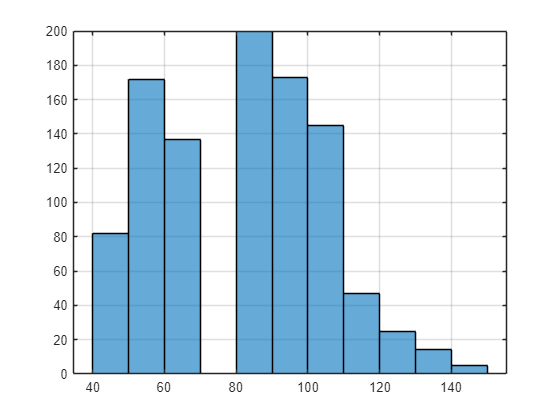

data = readtable("./data/overLandAndSea.csv");
landWS = data.landWS;
seaWS = data.seaWS;
ws = data.ws;
histogram(ws)
grid on

## Task 1

A histogram is a bit like a bar plot in that it uses bar heights to represent quantity.  In the starter code, a vector of windspeeds is passed as input to the histogram function.  Instead of one bar for each windspeed, the height of a bar represents how many measurements are in that range.  Each bin contains a range of three miles per hour.  For instance, the tallest bar indicates that there were 4335 measurements between 39 and 42 miles per hour.

Three miles per hour is a pretty tight range, and many data are more commonly reported in intervals of five or ten.  A common customization for histogram plots is to edit the width or the total number of bins.  

`histogram``(``vec``,``"BinWidth"``,``n``)`

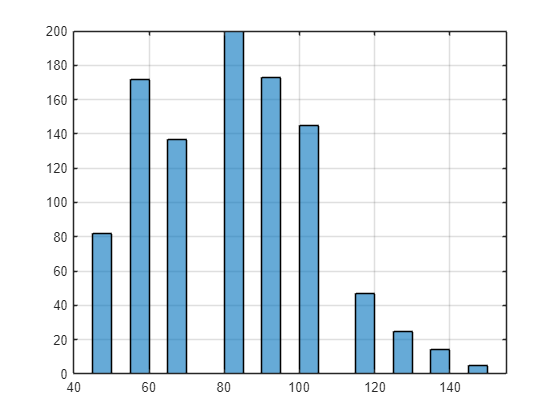

histogram(ws, "BinWidth", 5)
grid on

## Task 2

If you are more interested in the number of bins than the specific width, you can set that as a second input to `histogram`.

`histogram``(``vec``,``numBins``)`

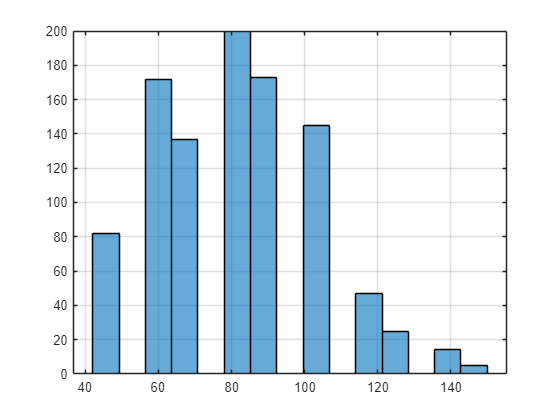

histogram(ws, 15)
grid on

## Task 3

The windspeed measurements taken on sea and land are in `seaWS` and `landWS` respectively.  To compare their distributions, you can plot histograms on top of each other with `hold on` and `hold off` just like other plot types.

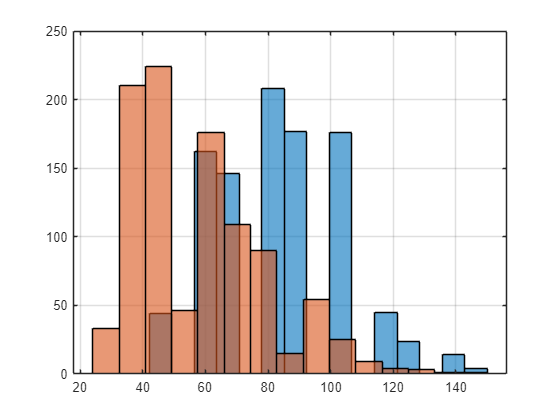

histogram(seaWS, 15)
hold on
histogram(landWS, 15)
hold off
grid on

## Tasks 4 and 5

There are many more measurements taken at sea than on land.  If you are trying to get a sense for the comparative distributions, it can be helpful to normalize the histograms.  You can set the normalization with a name-value pair.

`histogram``(``vec``,``numBins``,``"Normalization"``,``method``)`

There are several normalization methods you can use.  The `"probability"` method uses the relative probabilities as the heights of the bars (e.g. the number of measurements in each bin divided by the total number of measurements).

The histograms are skewed differently.  The speeds over sea are higher than over land, which you would expect since hurricanes slow down when they come ashore.  

You may also notice transparency allows you to see the histogram underneath.  You can control the alpha value with the `FaceAlpha` property.

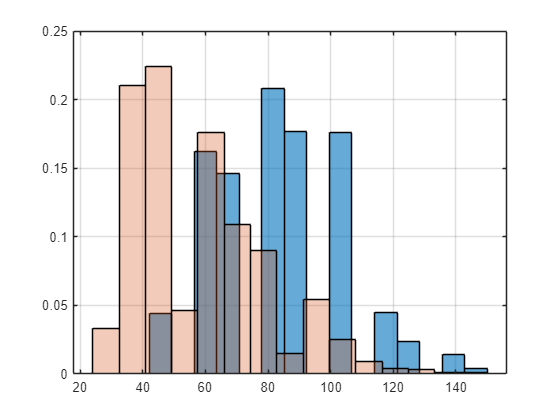

histogram(seaWS, 15, "Normalization", "probability")
hold on
histogram(landWS, 15, "Normalization", "probability", "FaceAlpha", .3)
hold off
grid on

## Task 6

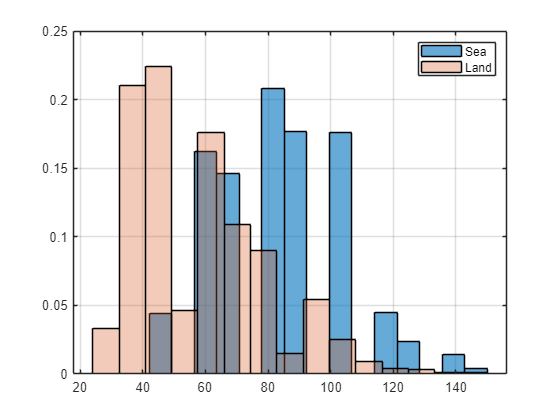

legend("Sea", "Land")